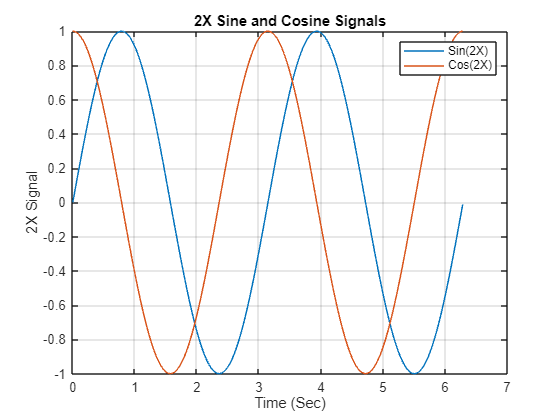

%% Initialization
clc; clear;

%% Parameters
L = 1024; % Signal length
Fs = 1024 / (2 * pi); % Sampling frequency
Freq = Fs * (0:(L/2)) / L; % Frequency range for plotting
time = linspace(0, 2 * pi, L); % Time vector

%% 2X Frequency Components
Sin2X = ReadBinaryFile('2X_sin_output.txt');
Cos2X = ReadBinaryFile('2X_cos_output.txt');

Func2 = Sin2X + 1i * Cos2X;
Func2_FFT = fft(Func2);

figure;
plot(time, Sin2X, time, Cos2X);
xlabel("Time (Sec)");
ylabel("2X Signal");
title("2X Sine and Cosine Signals");
legend("Sin(2X)", "Cos(2X)");
grid on;

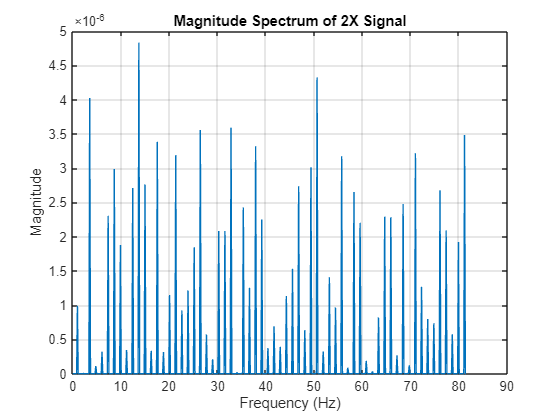


figure;
plot(Freq, abs(Func2_FFT(1:L/2+1)) / L);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of 2X Signal');
grid on;

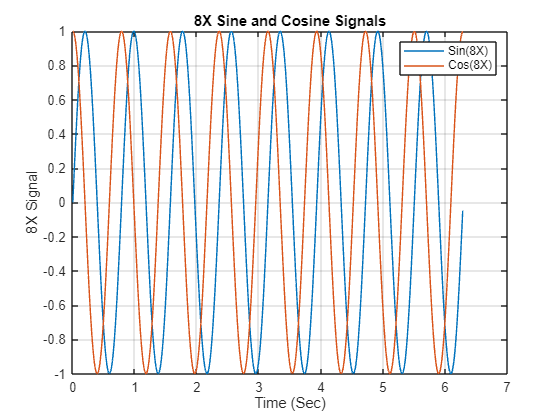


%% 8X Frequency Components
Sin8X = ReadBinaryFile('8X_sin_output.txt');
Cos8X = ReadBinaryFile('8X_cos_output.txt');

Func8 = Sin8X + 1i * Cos8X;
Func8_FFT = fft(Func8);

figure;
plot(time, Sin8X, time, Cos8X);
xlabel("Time (Sec)");
ylabel("8X Signal");
title("8X Sine and Cosine Signals");
legend("Sin(8X)", "Cos(8X)");
grid on;

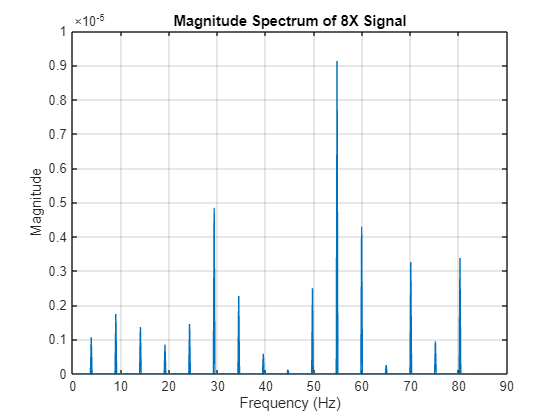


figure;
plot(Freq, abs(Func8_FFT(1:L/2+1)) / L);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of 8X Signal');
grid on;


%% Function for Reading Binary Files
function Out = ReadBinaryFile(filename)
    fid = fopen(filename, 'r');
    binary_data = textscan(fid, '%s');
    fclose(fid);
    
    decimal_data = bin2dec(binary_data{1});
    negative_indices = decimal_data > 2^(16-1) - 1;
    decimal_data(negative_indices) = decimal_data(negative_indices) - 2^16;
    
    Out = decimal_data / 2^14; % Adjusting for fractional bits
end
